## Workflow - Load pressure Data in Matlab and perform analysis

The LEAP 4000XHR software system records the vacuum level of the three different chambers and the temperature. This data can be copied and saved a .csv file. This data can be read in with Matlab and later assigned to each measurement with the Workflow_HDF5_measurement_condition.mlx

The workflow starts with the exported .csv file from the atom probe and ends with a VacPresLEAP table that contains information about the vacuum level in the three different chambers and the temperature over time.

At the end it is also possible to plot the Vacuum level over time. 

## Load Data in Matlab

find Data in folder structure

fileExcel = struct2table(dir('**/*.csv'));

set the options for importing the .csv files from LEAP

opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date", "Time", "Buffer", "LoadLock", "Analysis", "AnalysisUHV", "IonPump", "CryoTempChA", "CryoTempChB", "CryoHeaterOutput"];
opts.VariableTypes = ["char", "datetime", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Date", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Date", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Time", "InputFormat", "HH:mm:ss");
opts = setvaropts(opts, "Analysis", "TrimNonNumeric", true);
opts = setvaropts(opts, "Analysis", "ThousandsSeparator", ",");

% counter to check if it is the first table or if the table for all data
% already exist
r = 1;


Load data to Matlab

go through each file in the folder structure and add it to the variable VacPresLEAP

for i = 1:height(fileExcel)

    filepath = string([fileExcel.folder{i}  '\'  fileExcel.name{i}]);
    % Import the data
    VacPresLEAPNew = readtable(filepath, opts);
    % Delete the first two rows
    VacPresLEAPNew(1:2,:) = [];
    
    % add table to one big table containing the entire information 
    if r ==1
        VacPresLEAP = VacPresLEAPNew;
        r = 2;
    else
        VacPresLEAP = [VacPresLEAP; VacPresLEAPNew];
    end

end



## Change date to Datetime and the right Format

dateFormat = datetime(VacPresLEAP.Date,'InputFormat','MM/dd/yy');
VacPresLEAP = addvars(VacPresLEAP, dateFormat, 'after', 'Date');
VacPresLEAP.dateFormat.Format = "uuuu-MM-dd HH:mm:ss.SSS";
VacPresLEAP.Time.Format = "uuuu-MM-dd HH:mm:ss.SSS";
dateTime = VacPresLEAP.dateFormat + timeofday(VacPresLEAP.Time);
VacPresLEAP = addvars(VacPresLEAP, dateTime, 'after', 'dateFormat');


## Store variable in current Folder

save("2016_2023_VacPres_LEAP.mat", "VacPresLEAP", '-mat')
clearvars dateFormat dateTime fileExcel filepath i opts r VacPresLEAPNew

## Plot the Vacuum level over time

All 3 different chambers

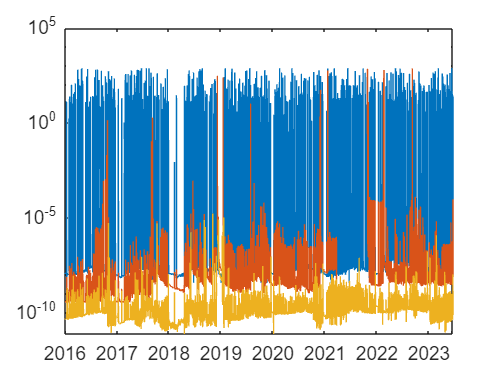

figure; 
plot(VacPresLEAP.dateFormat, VacPresLEAP.LoadLock, 'DisplayName', 'LoadLock');
hold on
plot(VacPresLEAP.dateFormat, VacPresLEAP.Buffer, 'DisplayName', 'Buffer');
hold on 
plot(VacPresLEAP.dateFormat, VacPresLEAP.AnalysisUHV, 'DisplayName', 'Analysis');


% properties of figure
ax = gca;
ax.YScale = 'log';